Cargamos los datos medidos.

motor_data = load('motor_data\all_data.mat')

motor_data = struct with fields:
    motor00V: [1×1 Simulink.SimulationData.Dataset]
    motor01V: [1×1 Simulink.SimulationData.Dataset]
    motor02V: [1×1 Simulink.SimulationData.Dataset]
    motor03V: [1×1 Simulink.SimulationData.Dataset]
    motor04V: [1×1 Simulink.SimulationData.Dataset]
    motor05V: [1×1 Simulink.SimulationData.Dataset]
    motor06V: [1×1 Simulink.SimulationData.Dataset]
    motor07V: [1×1 Simulink.SimulationData.Dataset]
    motor08V: [1×1 Simulink.SimulationData.Dataset]
    motor09V: [1×1 Simulink.SimulationData.Dataset]
    motor10V: [1×1 Simulink.SimulationData.Dataset]
    motor11V: [1×1 Simulink.SimulationData.Dataset]
    motor12V: [1×1 Simulink.SimulationData.Dataset]


Posiciones.

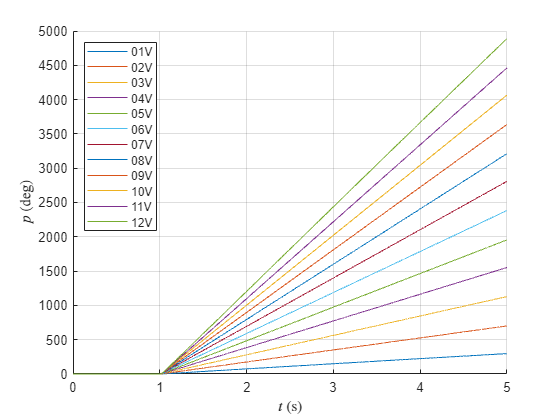

figure
hold on
for i = 1:12
    % Extracción de datos
    % Los archivos tienen el formato motorXXV, siendo XX el voltage
    % suministrado al motor
    voltage = pad(num2str(i), 2, "left", '0');
    extracted = motor_data.(strcat('motor',voltage,'V')).getElement('Motor:1');
    positions = extracted.Values.Data;
    time = extracted.Values.Time;
    % Representación
    plot(time, positions, DisplayName=strcat(voltage,'V'))
    grid on
end
legend(Location="northwest")
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$p$ (deg)', Interpreter='latex')
exportgraphics(gcf,'figuras\posicionLazoAbierto.pdf')

Velocidades.

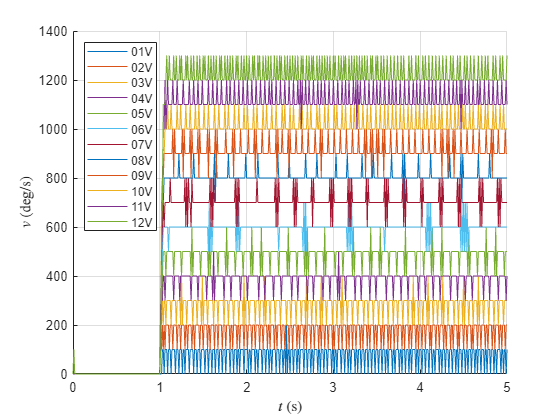

figure
hold on
for i = 1:12
    % Extracción de datos
    voltage = pad(num2str(i), 2, "left", '0');
    extracted = motor_data.(strcat('motor',voltage,'V')).getElement('Motor:2');
    positions = extracted.Values.Data;
    time = extracted.Values.Time;
    % Representación
    plot(time, positions, DisplayName=strcat(voltage,'V'))
    grid on
end
legend(Location="northwest")
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$v$ (deg/s)', Interpreter='latex')
xlim([0 5])
exportgraphics(gcf,'figuras\velocidadLazoAbierto.pdf')

Comprobación de encoders.

encoder_data = load('motor_data\encoders_raw.mat')

encoder_data = struct with fields:
    data: [1×1 Simulink.SimulationData.Dataset]


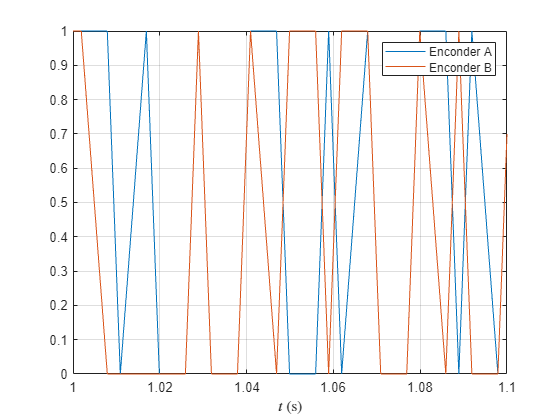

encoderA = encoder_data.data.getElement('Encoder A:1').Values.Data;
timeA = encoder_data.data.getElement('Encoder A:1').Values.Time;
encoderB = encoder_data.data.getElement('Encoder B:1').Values.Data;
timeB = encoder_data.data.getElement('Encoder B:1').Values.Time;
figure
plot(timeA, encoderA(:), DisplayName='Enconder A')
hold on
plot(timeB, encoderB(:), DisplayName='Enconder B')
grid on
legend
xlim([1 1.1])
xlabel('$t$ (s)', Interpreter='latex')
exportgraphics(gcf,'figuras\encodersCheck.pdf')